# Example 4.8: Simulating the Extreme Value Theorem

Note: this script reproduces Example 4.8 (Section 4.3.4) of **Statistics for Chemical Engineers**: the distribution of the maximum of S observations of N(2,1). Victor Z UW-Madison, 2020 simulating the extreme value theorem (evt)

clc; clear all;  close all hidden; 

rng(0)
N=1000;  % number of samples

figure(1)
subplot(2,2,1)
xgrid=linspace(2-5,2+7,1000);
plot(xgrid,normpdf(xgrid,2,1),'black','LineWidth',1.5)
xlabel('$x$','Interpreter','latex','FontSize',14)
ylabel('$f(x)$','Interpreter','latex','FontSize',14)
grid on
axis([-3 7 0 0.5])

S=10; % sample size
for j=1:N
    x = normrnd(2,1,S,1);
    m(j) = max(x);
end

subplot(2,2,2)
histogram(m,'Normalization','pdf','EdgeColor','black','FaceColor','none','LineWidth',1)
xlabel('$x_{max}$','Interpreter','latex','FontSize',14)
ylabel('$f(x_{max})$','Interpreter','latex','FontSize',14)
grid on
axis([2 7 0 1.5])

S=100;  % number of samples
for j=1:N
    x = normrnd(2,1,S,1);
    m(j) = max(x);
end
subplot(2,2,3)
histogram(m,'Normalization','pdf','EdgeColor','black','FaceColor','none','LineWidth',1)
xlabel('$x_{max}$','Interpreter','latex','FontSize',14)
ylabel('$f(x_{max})$','Interpreter','latex','FontSize',14)
grid on
axis([2 7 0 1.5])

S=1000;  % number of samples
for j=1:N
    x = normrnd(2,1,S,1);
    m(j) = max(x);
end
pd = fitdist(m','GeneralizedExtremeValue')

pd =   GeneralizedExtremeValueDistribution

  Generalized Extreme Value distribution
        k = -0.0678591   [-0.110653, -0.0250656]
    sigma =   0.310782   [0.295869, 0.326447]
       mu =    5.09752   [5.07599, 5.11904]


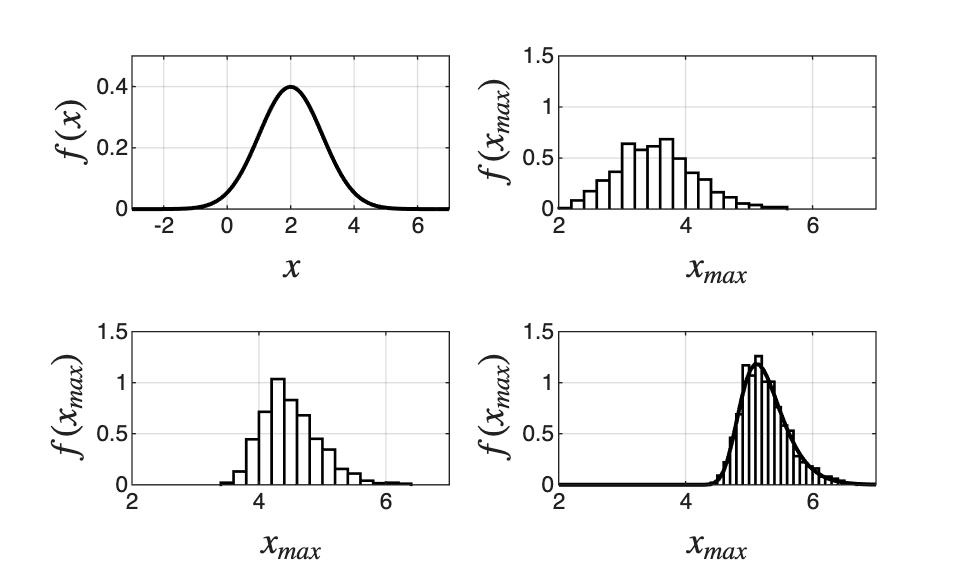

xx=linspace(0,7);

subplot(2,2,4)
histogram(m,'Normalization','pdf','EdgeColor','black','FaceColor','none','LineWidth',1)
hold on
plot(xx,gevpdf(xx,pd.k,pd.sigma,pd.mu),'black','LineWidth',1.5)
xlabel('$x_{max}$','Interpreter','latex','FontSize',14)
ylabel('$f(x_{max})$','Interpreter','latex','FontSize',14)
grid on
axis([2 7 0 1.5])

print -depsc ch4_evt_weibull.eps

## Probabilities of large peaks

determine probability P(X>5)

P=1-gevcdf(5,pd.k,pd.sigma,pd.mu)

P =    7.4438e-01


% determine probability P(X>7)
P=1-gevcdf(7,pd.k,pd.sigma,pd.mu)

P =    3.6660e-04

## Note

As in the book, for S = 1000 the peak is likely above 5 but unlikely above 7 (P = 3.6e-4); these probabilities come from the extreme value model, without knowing the nature of X.